# Gradient Attribution

#### Fred liu 2022.5.20

**載入模型與影像(Load Model & Image)**

net = resnet50;
img = imread("t02.jpg");

**影像辨識(Image Classify)**

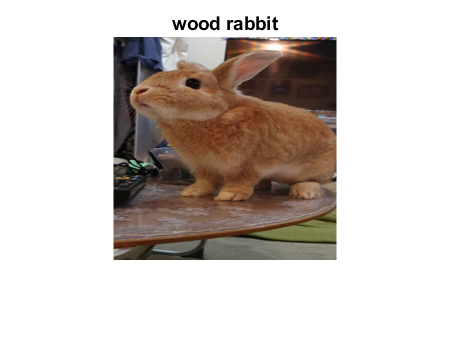

inputSize = net.Layers(1).InputSize(1:2);
classes = net.Layers(end).Classes;

re_img = imresize(img,inputSize);
figure,imshow(re_img)

[YPred,scores] = classify(net,re_img);
title(char(YPred))

**GradientAttribution**

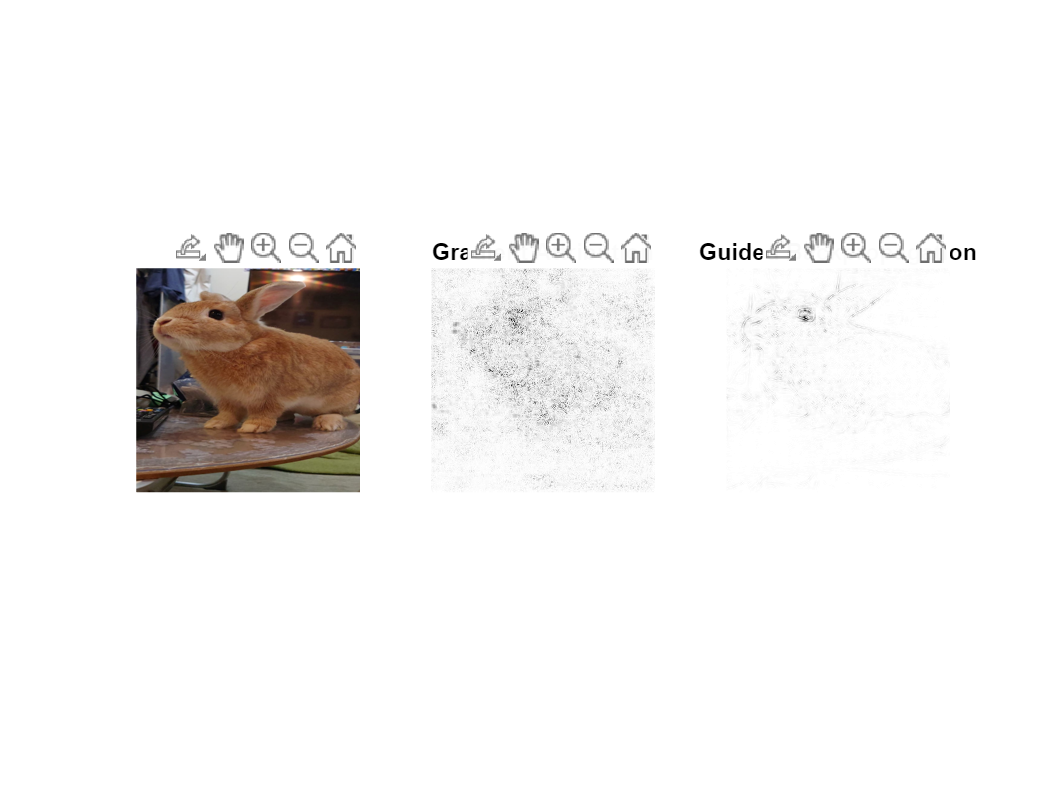

softmaxName = 'fc1000_softmax';
pixelMap = gradientAttribution(net,re_img,YPred,softmaxName,"autodiff");

pixelGuidedBackpropMap = gradientAttribution(net,re_img,YPred,softmaxName,"guided-backprop");

alpha = 1;
cmap = [linspace(1,0,255)' linspace(1,0,255)' linspace(1,0,255)'];
plotMaps(re_img,pixelMap,pixelGuidedBackpropMap, ...
    "Gradient Attribution","Guided Backpropagation",alpha,cmap)

**Gradient Attribution Map Function**

function map = gradientAttribution(net,img,YPred,softmaxName,method)

lgraph = layerGraph(net);
lgraph = removeLayers(lgraph,lgraph.Layers(end).Name);
dlnet = dlnetwork(lgraph);

% To use automatic differentiation, convert the image to a dlarray.
dlImg = dlarray(single(img),"SSC");

if method == "autodiff"
% Use dlfeval and the gradientMap function to compute the derivative. The gradientMap
% function passes the image forward through the network to obtain the class scores
% and contains a call to dlgradient to evaluate the gradients of the scores with respect
% to the image.
dydI = dlfeval(@gradientMap,dlnet,dlImg,softmaxName,YPred);
end

if method == "guided-backprop"

% Use the custom layer CustomBackpropReluLayer (attached as a supporting file)  
% with a nonstandard backward pass, and use it with automatic differentiation.
customRelu = CustomBackpropReluLayer();

% Set the BackpropMode property of each CustomBackpropReluLayer to "guided-backprop".
customRelu.BackpropMode = "guided-backprop";

% Use the supporting function replaceLayersOfType to replace all instances of reluLayer in the network with
% instances of CustomBackpropReluLayer. 
lgraphGB = replaceLayersOfType(lgraph, ...
    'nnet.cnn.layer.ReLULayer',customRelu);

% Convert the layer graph containing the CustomBackpropReluLayers into a dlnetwork.
dlnetGB = dlnetwork(lgraphGB);
dydI = dlfeval(@gradientMap,dlnetGB,dlImg,softmaxName,YPred);
end

% Sum the absolute values of each pixel along the channel dimension, then rescale
% between 0 and 1.
map = sum(abs(extractdata(dydI)),3);
map = rescale(map);
end

function dydI = gradientMap(dlnet,dlImgs,softmaxName,classIdx)

dydI = dlarray(zeros(size(dlImgs)));

for i=1:size(dlImgs,4)
    I = dlImgs(:,:,:,i);
    scores = predict(dlnet,I,'Outputs',{softmaxName});
    classScore = scores(classIdx);
    dydI(:,:,:,i) = dlgradient(classScore,I);
end
end

function lgraph = replaceLayersOfType(lgraph,layerType,newLayer)

% Replace layers in the layerGraph lgraph of the type specified by
% layerType with copies of the layer newLayer.

for i=1:length(lgraph.Layers)
    if isa(lgraph.Layers(i),layerType)
        % Match names between the old and new layers.
        layerName = lgraph.Layers(i).Name;
        newLayer.Name = layerName;
        
        lgraph = replaceLayer(lgraph,layerName,newLayer);
    end
end
end

function plotMaps(img,map1,map2,title1,title2,alpha,cmap)

figure
subplot(1,3,1)
imshow(img)

subplot(1,3,2)
imshow(img)
hold on
imagesc(map1,'AlphaData',alpha)
colormap(cmap)
title(title1)
hold off

subplot(1,3,3)
imshow(img)
hold on
imagesc(map2,'AlphaData',alpha)
colormap(cmap)
title(title2)
hold off
end